clear
clc


load lasertrain.dat
load laserpred.dat

% standardize the datasets
mu = mean(lasertrain);
sig = std(lasertrain);


trainset = (lasertrain - mu) / sig;
predset = (laserpred - mu) / sig;

% get time series train data
p = 200; % define the number of lags
% get the training data 
[TrainData,TrainTarget]=getTimeSeriesTrainData(trainset, p);

[trainInd,valInd,testInd] = divideblock(size(TrainData,2),0.6,0.2,0.2);

% training set 
x_train = TrainData(:,trainInd);
t_train = TrainTarget(:,trainInd);

% validation set 
x_val = TrainData(:,valInd);
t_val = TrainTarget(:,valInd);

% test set 

x_test = TrainData(:,testInd);
t_test = TrainTarget(:,testInd);

% Configuration

% traingd gradient descent
% traingda gradient descent with adaptive learning rate
% traincgf Fletcher-Reeves conjugate gradient algorithm
% traincgp Polak-Ribiere conjugate gradient algorithm
% trainbfg - BFGS (quasi Newton)
% trainlm - Levenberg - Marquardt
alg = 'trainlm';% First training algorithm to use
H = 50;% Number of neurons in the hidden layer
delta_epochs = [1,14,25,30,30];% Number of epochs to train in each step
epochs = cumsum(delta_epochs);

% Creation of network
net=feedforwardnet(H,alg);
% configure the transfer function 
% logsig
% tansig
% pureline
net.layers{1}.transferFcn = 'tansig';
net=configure(net,x_train,t_train);% Set the input and output sizes of the net
net.divideFcn = 'dividetrain';% Use training set only (no validation and test split)
net=init(net);% Initialize the weights (randomly)

%training 
net.trainParam.epochs=delta_epochs(1);  % set the number of epochs for the training 
net=train(net,x_train,t_train);   % train the networks

% estimate the target using train network with train, val, test set
t1=sim(net,x_train);
v1=sim(net,x_val);
a1=sim(net,x_test);


net.trainParam.epochs=delta_epochs(2);  % set the number of epochs for the training 
net=train(net,x_train,t_train);   % train the networks

% pick up the model after 15 epoches 

a_net = net;

%

% estimate the target using train network with train, val, test set
t2=sim(net,x_train);
v2=sim(net,x_val);
a2=sim(net,x_test);



net.trainParam.epochs=delta_epochs(3);  % set the number of epochs for the training 
net=train(net,x_train,t_train);   % train the networks

% estimate the target using train network with train, val, test set
t3=sim(net,x_train);
v3=sim(net,x_val);
a3=sim(net,x_test);

net.trainParam.epochs=delta_epochs(4);  % set the number of epochs for the training 
net=train(net,x_train,t_train);   % train the networks

% estimate the target using train network with train, val, test set
t4=sim(net,x_train);
v4=sim(net,x_val);
a4=sim(net,x_test);

net.trainParam.epochs=delta_epochs(5);  % set the number of epochs for the training 
net=train(net,x_train,t_train);   % train the networks

% a_net = net;

% estimate the target using train network with train, val, test set
t5=sim(net,x_train);
v5=sim(net,x_val);
a5=sim(net,x_test);



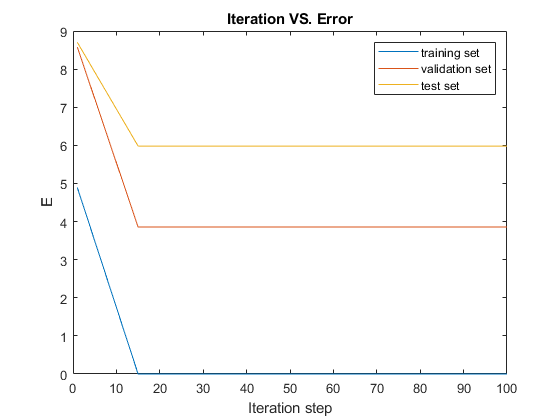

% validation of the network: hyperparameter tuning

% Calculate MSE of the training set 
MSE_t1 = perform(net,t1,t_train);
MSE_t2 = perform(net,t2,t_train);
MSE_t3 = perform(net,t3,t_train);
MSE_t4 = perform(net,t4,t_train);
MSE_t5 = perform(net,t5,t_train);

MSE_Train = [MSE_t1 MSE_t2 MSE_t3 MSE_t4 MSE_t5];

% Calculate MSE of the validation set 
MSE_v1 = perform(net,v1,t_val);
MSE_v2 = perform(net,v2,t_val);
MSE_v3 = perform(net,v3,t_val);
MSE_v4 = perform(net,v4,t_val);
MSE_v5 = perform(net,v5,t_val);

MSE_Val = [MSE_v1 MSE_v2 MSE_v3 MSE_v4 MSE_v5];

% Calculate MSE of the test set 
MSE_a1 = perform(net,a1,t_test);
MSE_a2 = perform(net,a2,t_test);
MSE_a3 = perform(net,a3,t_test);
MSE_a4 = perform(net,a4,t_test);
MSE_a5 = perform(net,a5,t_test);

MSE_Test = [MSE_a1 MSE_a2 MSE_a3 MSE_a4 MSE_a5];


figure('Name','Iteration VS. Error')

plot(epochs, MSE_Train, epochs, MSE_Val,epochs, MSE_Test)
legend('training set','validation set','test set');
title('Iteration VS. Error');
xlabel('Iteration step');
ylabel('E');

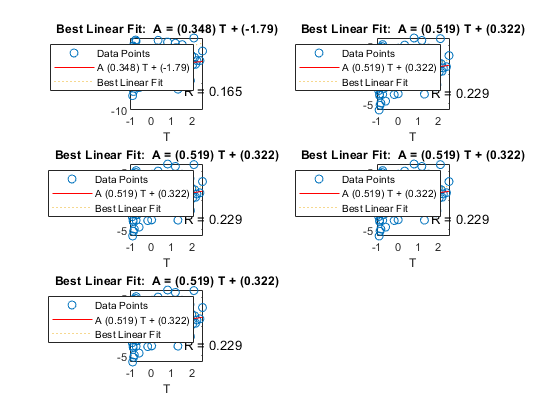

% Evaluation on the test set 
figure 
subplot(3,2,1)
postregm(a1,t_test); % perform a linear regression analysis and plot the result
subplot(3,2,2)
postregm(a2,t_test); % perform a linear regression analysis and plot the result
subplot(3,2,3)
postregm(a3,t_test); % perform a linear regression analysis and plot the result
subplot(3,2,4)
postregm(a4,t_test); % perform a linear regression analysis and plot the result
subplot(3,2,5)
postregm(a5,t_test); % perform a linear regression analysis and plot the result

% use the a_net for the prediction set 

% create a array for storing predictions

t_pred = zeros(size(predset));

% create and initialize the temp_input vector with last # lag train dataset
temp_input = trainset(end-p+1:end);




% use a for loop to do the prediction: for each step, first predict the
% output using temp input vector, then store the value and update the temp
% iput vector. 

predset_size = size(predset);


for i = 1:predset_size(1)
    
    temp_output = sim(a_net,temp_input);
    t_pred(i) = temp_output;
    
    % update temp_input
    
    for j = 1:(p-1)
        temp_input(j) = temp_input(j+1);
    end
    
    temp_input(p) = temp_output;
               
end


% Unstandardize the predictions using the parameters calculated earlier.
t_pred = sig*t_pred + mu;
predset = sig*predset + mu;


rmse = sqrt(mean((t_pred-predset).^2))

rmse = 129.6761

disp(rmse)

  129.6761



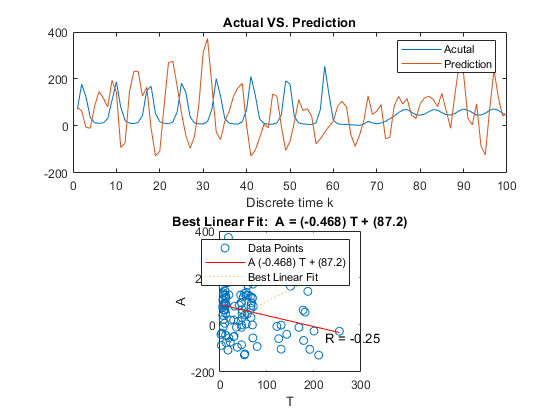





% compare the predicted value vs. actual value in the graph
% plot predset vs t_pred
x = (1:100)';

figure('Name','Actual Value VS. Prediction Value ')
subplot(2,1,1)
plot(x,predset,x,t_pred)
legend('Acutal','Prediction');
title('Actual VS. Prediction');
xlabel('Discrete time k');
subplot(2,1,2)
postregm(t_pred',predset'); % perform a linear regression analysis and plot the result